# ADSP 14 Oct. 2021

clc; clear;

load ADSP_exercising30Sept21.mat
Fs = 8e3;
%x = y(4430:6800);     % Segmentation and reassignment to x
x = y(5000:5999);
clear y;
% sound(x, Fs)        % Uncomment to sound the audio signal


## Monte-Carlo Simulation

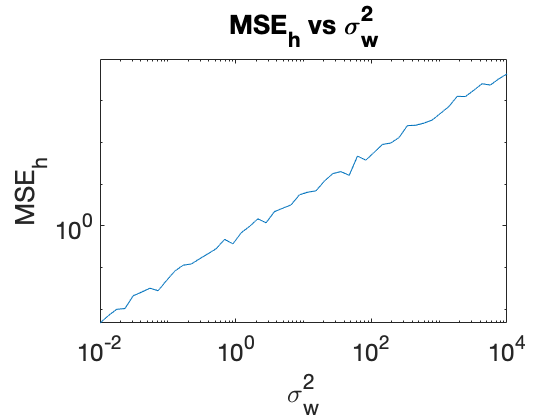

% Define simulation parameters:
Nx = length(x);                     % length of input signal
Ns = 50;                            % number of simulated noise powers
Nmc = 50;                          % number of monte-carlo iterations
sigma_w = logspace(-1, 2, Ns);      % set of noise power

% Memory allocation
MSE_h = zeros(1, Ns);
MSE_x = zeros(1, Ns);
MSE_xclean = zeros(1, Ns);

% Define filter impulse response h[n]
h = [1, -1]';
x_con = conv(x, h);     % Filtered signal
Nh = length(h);         % Length of the filter inpulse response
Nc = Nx + Nh - 1;        % length of the convoluted signal


for n = 1 : Nmc

    for k = 1 : Ns
        
        % Generate random noise sequence with power sigma_w^2(k_sigma)
        w = sigma_w(k) * randn(Nc, 1);
        
        % Measured signal (after noise)
        y = x_con + w;
        
        % Define the convolution matrix of the input signal:
        X = zeros(Nc, Nh);
        for i = 1 : Nh
            X(i:Nx-1+i,i) = x;            
        end
        
        % Estimate the impulse response of the filter h
        h_est = pinv(X) * y;
        MSE_h(k,n) = mean((h_est - h).^2);                              % MSE of filters' tap
        MSE_x(k,n) = mean((X * h_est - y).^2) / Nc;              % MSE of data-out (practical choice in many context)
        MSE_xclean(k,n) = mean((X * h_est - x_con).^2) / Nc;     % MSE of data out of filter (specific analysis on filter)
    end
end

figure;
loglog(sigma_w.^2, mean(MSE_h,2))
title('MSE_h vs \sigma^2_w')
xlabel('\sigma_w^2')
ylabel('MSE_h')
set(gca, 'FontSize', 24)

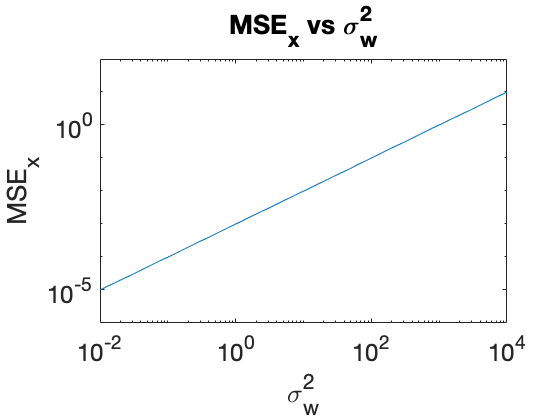


figure; 
loglog(sigma_w.^2, mean(MSE_x,2))
title('MSE_x vs \sigma^2_w')
xlabel('\sigma_w^2')
ylabel('MSE_x')
set(gca, 'FontSize', 24)

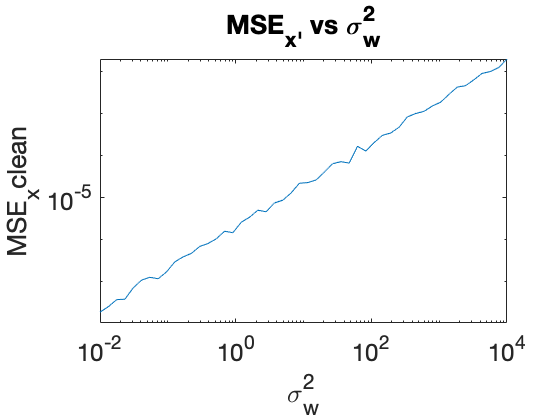


figure;
loglog(sigma_w.^2, mean(MSE_xclean,2))
title('MSE_x_'' vs \sigma^2_w')
xlabel('\sigma_w^2')
ylabel('MSE_xclean')
set(gca, 'FontSize', 24)

## Noise generation with arbitraty covariance matrix


% Noise parameters:
rho = 0.5;
sigma2_u = 1;
Cw = sigma2_u * [1 -rho; -rho 1];   % Covariance matrix of the noise
Nw = 1e4;                           % Number of samples

u = randn(2,Nw);                    % White noise
w_c = chol(Cw, 'lower') * u;        % Cholesky method
w_s = sqrtm(Cw) * u;                % Sqrtm method

[U S V] = svd(Cw);                  % SVD method
w_svd = U*sqrt(S) * u;

disp('Cholesky: '), disp([cov(w_c.')])

Cholesky: 
    1.0137   -0.5036
   -0.5036    1.0067



disp('sqrtm method: '), disp([cov(w_s.')])

sqrtm method: 
    1.0115   -0.5019
   -0.5019    1.0072



disp('SVD method: '), disp([cov(w_svd.')])

SVD method: 
    1.0092   -0.5081
   -0.5081    1.0157



## Noise with AR(1) model:

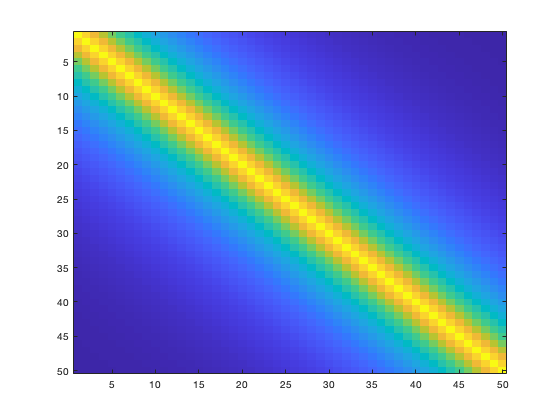

% AR model:   u[n] -> |AR(1)| -> w[n]
rho = 0.9;
N = 50;         % truncated sequence length
Nt = 1e3;       % Number of tests:

% Linear approach:
u = randn(N, Nt);
w = zeros(N, Nt);
for n = 2:N
    w(n,:) = u(n,:) + rho * w(n-1,:);
end

% Compute the covariance matrix:
Cw_est = cov(w.');
Cw_true = zeros(N,N);
for i = 1 : N
    for j = 1 : N
        Cw_true(i,j) = rho^abs(i-j) / (1-rho^2);
    end
end

figure;
imagesc(Cw_true);

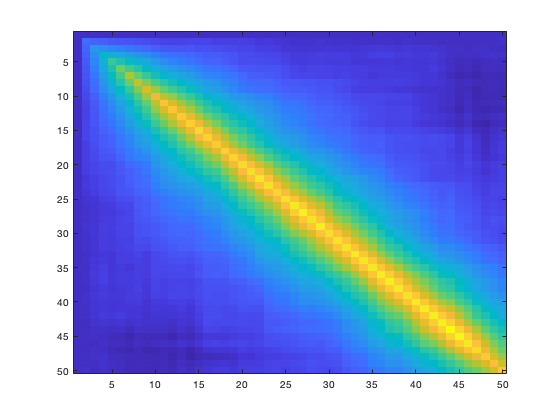

figure;
imagesc(Cw_est);

## System Identification with colored Noise:

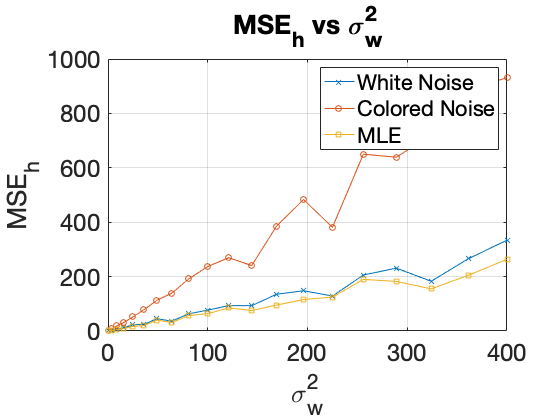

% Define simulation parameters:
x_new = x(1:500);
x = x_new;
Nx = length(x);                     % length of input signal
Ns = 20;                            % number of simulated noise powers
Nmc = 50;                          % number of monte-carlo iterations
sigma_w = 1:Ns;                     % set of noise power

% Memory allocation
MSE_h = zeros(1, Ns);
MSE_x = zeros(1, Ns);
MSE_xclean = zeros(1, Ns);
MSE_h_c = zeros(1, Ns);
MSE_x_c = zeros(1, Ns);
MSE_xclean_c = zeros(1, Ns);
MSE_h_c_ml = zeros(1, Ns);
MSE_x_c_ml = zeros(1, Ns);
MSE_xclean_c_ml = zeros(1, Ns);

% Define filter impulse response h[n]
h = [1, -1]';
x_con = conv(x, h);     % Filtered signal
Nh = length(h);         % Length of the filter inpulse response
Nc = Nx + Nh - 1;        % length of the convoluted signal


% Define AR parameters:
rho = 0.9;
Cw_true = zeros(Nc,Nc);
for i = 1 : Nc
    for j = 1 : Nc
        Cw_true(i,j) = rho^abs(i-j) / (1-rho^2);
    end
end

for n = 1 : Nmc

    for k = 1 : Ns
        
        % Generate random noise sequence with power sigma_w^2(k_sigma)
        w = sigma_w(k) * randn(Nc, 1);
        
        % Generate random noise sequence with Covariance Cw usign cholesky
        % factorization
        u = chol(Cw_true) * w;
        
        % Measured signal (after noise)
        y = x_con + w;
        y_c = x_con + u;
        
        % Define the convolution matrix of the input signal:
        X = zeros(Nc, Nh);
        for i = 1 : Nh
            X(i:Nx-1+i,i) = x;            
        end
        
        % Estimate the impulse response of the filter h
        h_est = X \ y;
        h_est_c = X \ y_c;
        Xml = (X.' / Cw_true * X) \ X.' / Cw_true;              % A / B, is equivalent to B \ A and it is an efficient way to compute A * B^(-1)
        h_est_c_ml = Xml * y_c;
        
        MSE_h(k,n) = mean((h_est - h).^2);                              % MSE of filters' tap
        MSE_x(k,n) = mean((X * h_est - y).^2) / Nc;              % MSE of data-out (practical choice in many context)
        MSE_xclean(k,n) = mean((X * h_est - x_con).^2) / Nc;     % MSE of data out of filter (specific analysis on filter)
        
        MSE_h_c(k,n) = mean((h_est_c - h).^2);                              % MSE of filters' tap
        MSE_x_c(k,n) = mean((X * h_est_c - y_c).^2) / Nc;              % MSE of data-out (practical choice in many context)
        MSE_xclean_c(k,n) = mean((X * h_est_c - x_con).^2) / Nc;     % MSE of data out of filter (specific analysis on filter)
        
        MSE_h_c_ml(k,n) = mean((h_est_c_ml - h).^2);                              % MSE of filters' tap
        MSE_x_c_ml(k,n) = mean((X * h_est_c_ml - y_c).^2) / Nc;              % MSE of data-out (practical choice in many context)
        MSE_xclean_c_ml(k,n) = mean((X * h_est_c_ml - x_con).^2) / Nc;     % MSE of data out of filter (specific analysis on filter)
    end
end

figure; hold on; box on; grid on;
plot(sigma_w.^2, mean(MSE_h,2),'-x')
plot(sigma_w.^2, mean(MSE_h_c,2),'-o')
plot(sigma_w.^2, mean(MSE_h_c_ml,2),'-s')
title('MSE_h vs \sigma^2_w')
xlabel('\sigma_w^2')
ylabel('MSE_h')
set(gca, 'FontSize', 24)
legend({'White Noise', 'Colored Noise', 'MLE'})

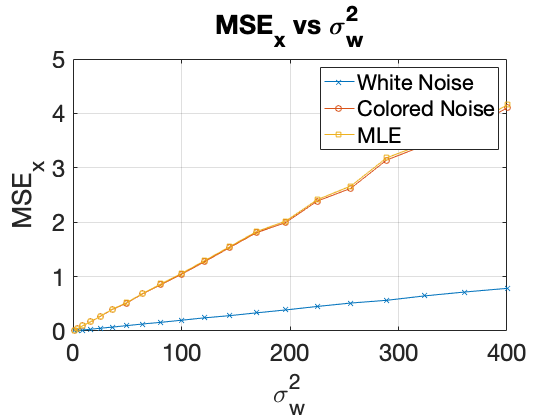


figure; hold on; box on; grid on;
plot(sigma_w.^2, mean(MSE_x,2),'-x')
plot(sigma_w.^2, mean(MSE_x_c,2),'-o')
plot(sigma_w.^2, mean(MSE_x_c_ml,2),'-s')
title('MSE_x vs \sigma^2_w')
xlabel('\sigma_w^2')
ylabel('MSE_x')
set(gca, 'FontSize', 24)
legend({'White Noise', 'Colored Noise', 'MLE'})

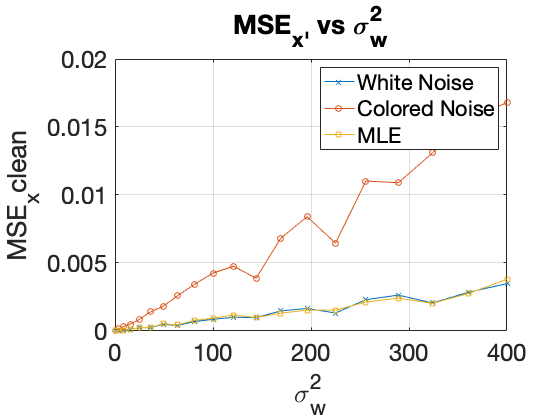


figure; hold on; box on; grid on;
plot(sigma_w.^2, mean(MSE_xclean,2),'-x')
plot(sigma_w.^2, mean(MSE_xclean_c,2),'-o')
plot(sigma_w.^2, mean(MSE_xclean_c_ml,2),'-s')
title('MSE_x_'' vs \sigma^2_w')
xlabel('\sigma_w^2')
ylabel('MSE_xclean')
set(gca, 'FontSize', 24)
legend({'White Noise', 'Colored Noise', 'MLE'})